# TASK_01:    **Derive and Implement 1-dof car model**

In this task we will:

- Develop a transverse (up and down) vibration model of a car.

- Represent the car by a 1-dof spring mass damper system

- Derive the **Equations of Motion**(EoM) of a simple 1-dof spring mass system using **Newton's 2nd Law**

- Implement the 1-dof spring mass equations into **Simulink** and simulate the model

- Connect the 1-dof spring mass system to a **road profile model**

- Implement the 1-dof spring mass system in **Simscape** and simulate the model

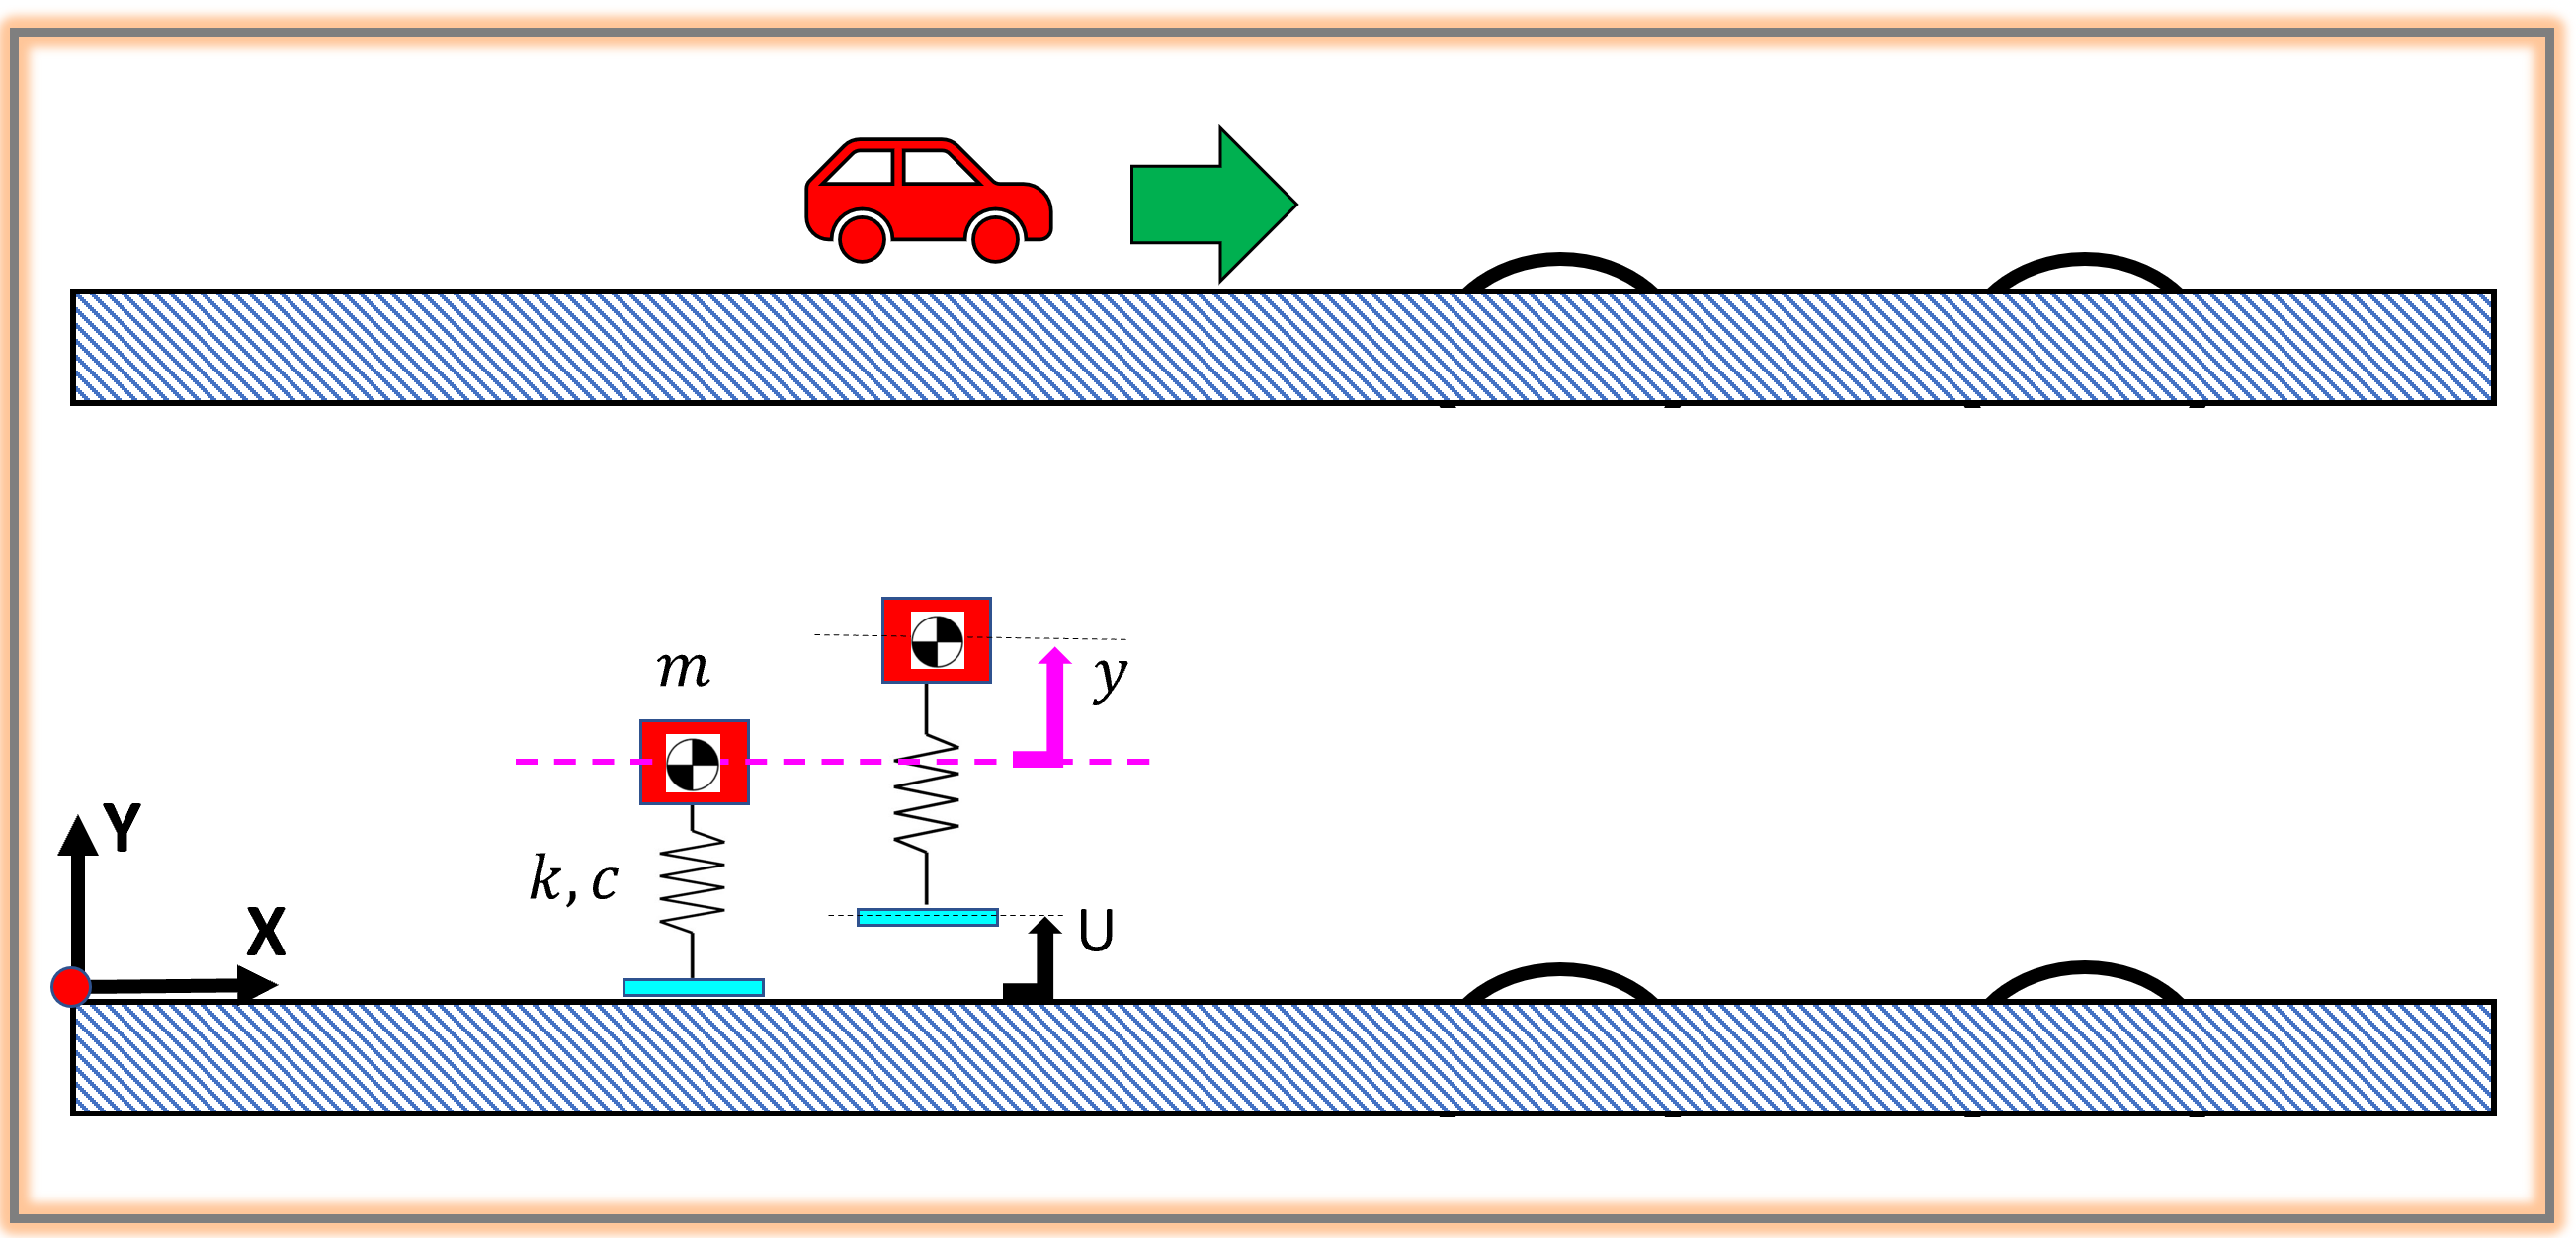

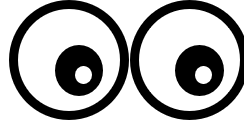 **Some resources for self review:**

If you're NEW to Simulink, I'd recommend doing the Self paced Online training course called the "Simulink Onramp":

- [**Simulink Onramp**](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink)

And the following DOC pages discuss some of the Simulink modeling concepts that we've used in this example:

- [**Creating a custom parameter dialogue interface(gui) on a Simulink subsystem - welcome to Masking**](https://au.mathworks.com/help/releases/R2026a/simulink/ug/block-masks.html)

- [**Referenced Subsystems - What are they ... and why should you use them ?**](https://au.mathworks.com/help/releases/R2026a/simulink/ug/create-and-use-referenced-subsystems-in-models-using-subsystem-reference.html)

`Bradley Horton : 6-Apr-2026, bhorton@mathworks.com`

## The Free Body diagram and Newton's 2nd Law

Consider the free body diagram shown below, where

- $m\;:\;\;$mass   *(kg)*

- $k\;:\;\;$spring stiffness co-efficient   *(N/m)*

- $c\;:\;\;$spring damping co-efficient   *(N/(m/s))*

- $y\;:\;\;$displacement of mass from equilibrium position   *(m)*

- $U\;:\;$road displacement   *(m)*

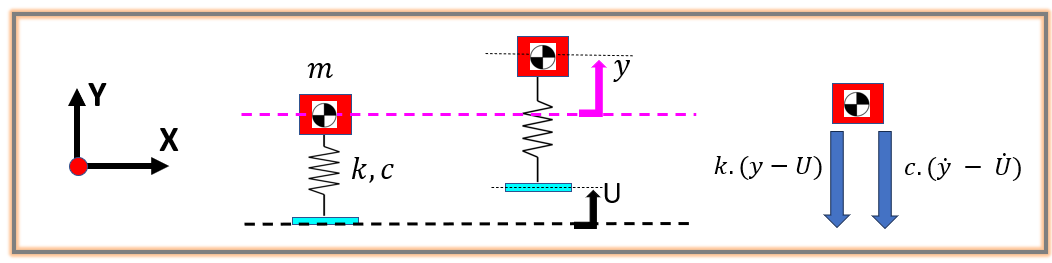

Applying Newton's 2nd Law in the Y-direction gives:

- 
$$m\ldotp \ddot{y} \;\;\;=\;\;\;\sum F_i \;\;\;=\;\;-k\ldotp \left(y-U\right)-c\ldotp \left(\dot{y} -\dot{U} \right)$$


- 
$$m\ldotp \ddot{y} \;\;=\;\;-k\ldotp y\;\;+\;k\ldotp U\;\;-c\ldotp \dot{y} \;\;+\;\;c\ldotp \dot{U}$$


And rearranging gives:

- 
$$m\ldotp \ddot{y} \;\;\;+\;c\ldotp \dot{y} \;\;+\;k\ldotp y\;\;=\;\;k\ldotp U\;\;+\;c\ldotp \dot{U}$$


Also,  isolating $\ddot{y}$ we get:

- 
$$\ddot{y} \;\;=\;\;\;\;\frac{-k\ldotp \left(y-U\right)-c\ldotp \left(\dot{y} -\dot{U} \right)}{m}$$


## STEP_00:    Load some model parameters into MATLAB's workspace

In preparation for the Simulink models that we'll be simulating, let's load some model parameters into the BASE workspace

**Press** the button below to run this code section

First clear your workspace

clear

Now load in the parameters defined in the script:

-  [`bh_TASK_00_model_parameters.mlx`](matlab:  edit bh_TASK_00_model_parameters.mlx)

bh_TASK_00_model_parameters

So what have we got ?

whos

  Name         Size            Bytes  Class     Attributes

  IC_T         1x1              1220  struct              
  env_T        1x1               165  struct              
  plant_T      1x1               403  struct              



For example here are the plant parameters

plant_T

plant_T = struct with fields:
    m: 5
    k: 500
    c: 12


And the Initial Conditions

IC_T

IC_T = struct with fields:
                y: 0
            y_dot: 0
             L_EQ: 1
              U_m: 1
          U_m_dot: 0
              U_R: 0
          U_R_dot: 0
        U_m_rel_R: 1
    U_m_rel_R_dot: 0


And our Environment parameters

env_T

env_T = struct with fields:
    g_vec: [0 0 0]


## STEP_01a:    Newton model

Here's a snapshot from the **Simulink** model of the 1-dof car that implements our Newton derivation.  The block diagram pattern uses integrator blocks (i.e. $\frac{1}{s}$ ) to represent ur expression for $\ddot{y}$

- 
$$\ddot{y} \;\;=\;\;\;\;\frac{-k\ldotp \left(y-U\right)-c\ldotp \left(\dot{y} -\dot{U} \right)}{m}$$


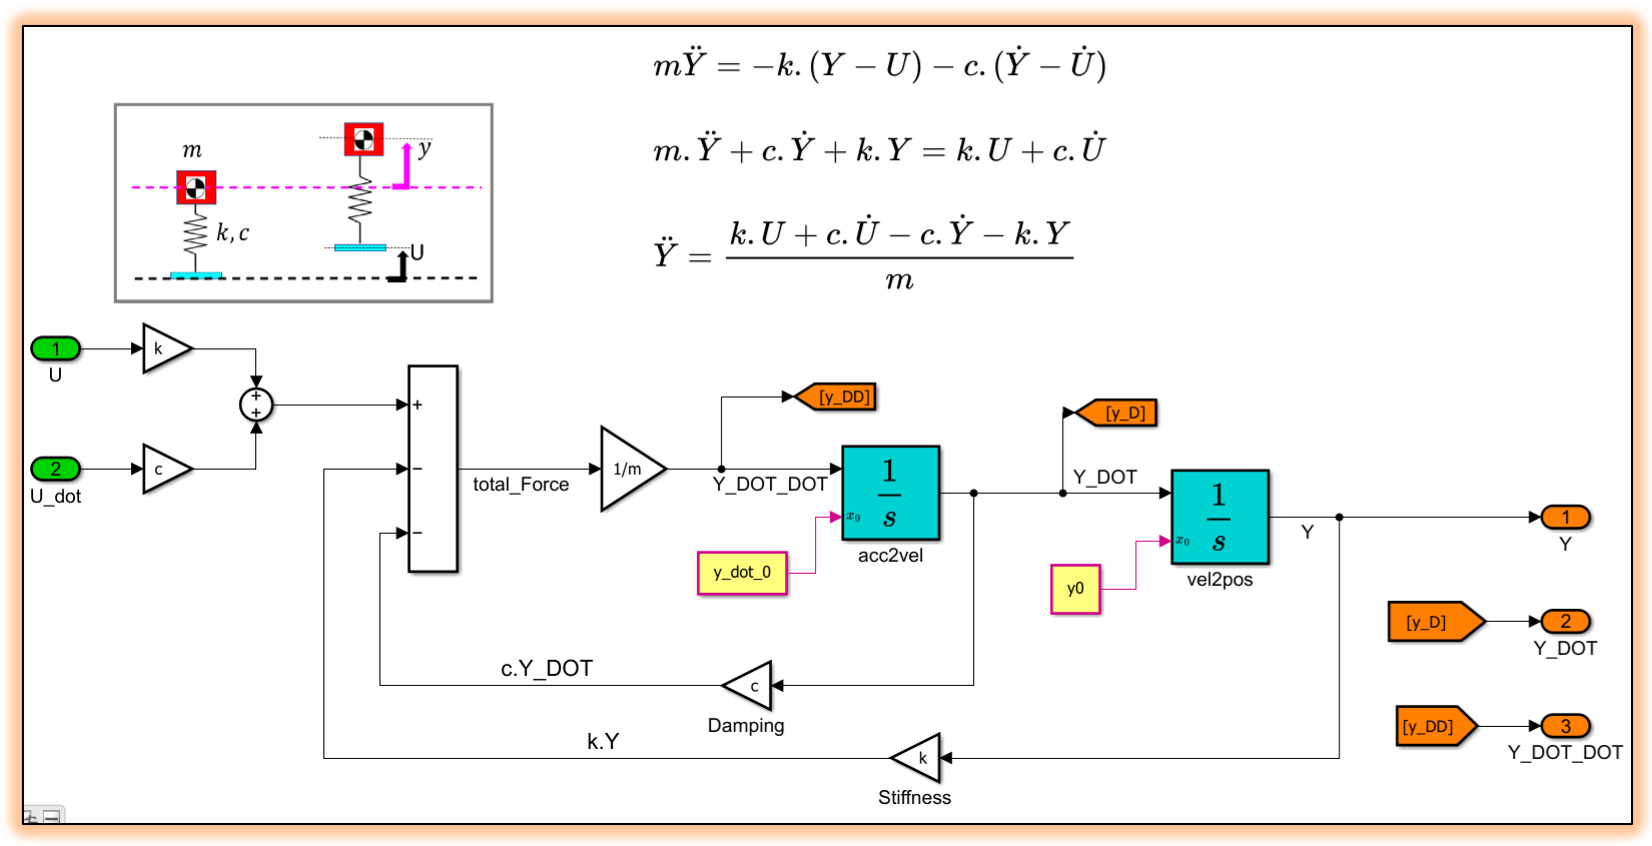

**Press** the button below to run this code section

Open the Simulink file:

open_system("bh_explore_1dof_Newton.slx")

 **NOTE:**  the car subsystem that contains our Newton derived equation of motion, has been "masked" - Masking allows us to create a custom dialogue gui for the subsystem i.e.:

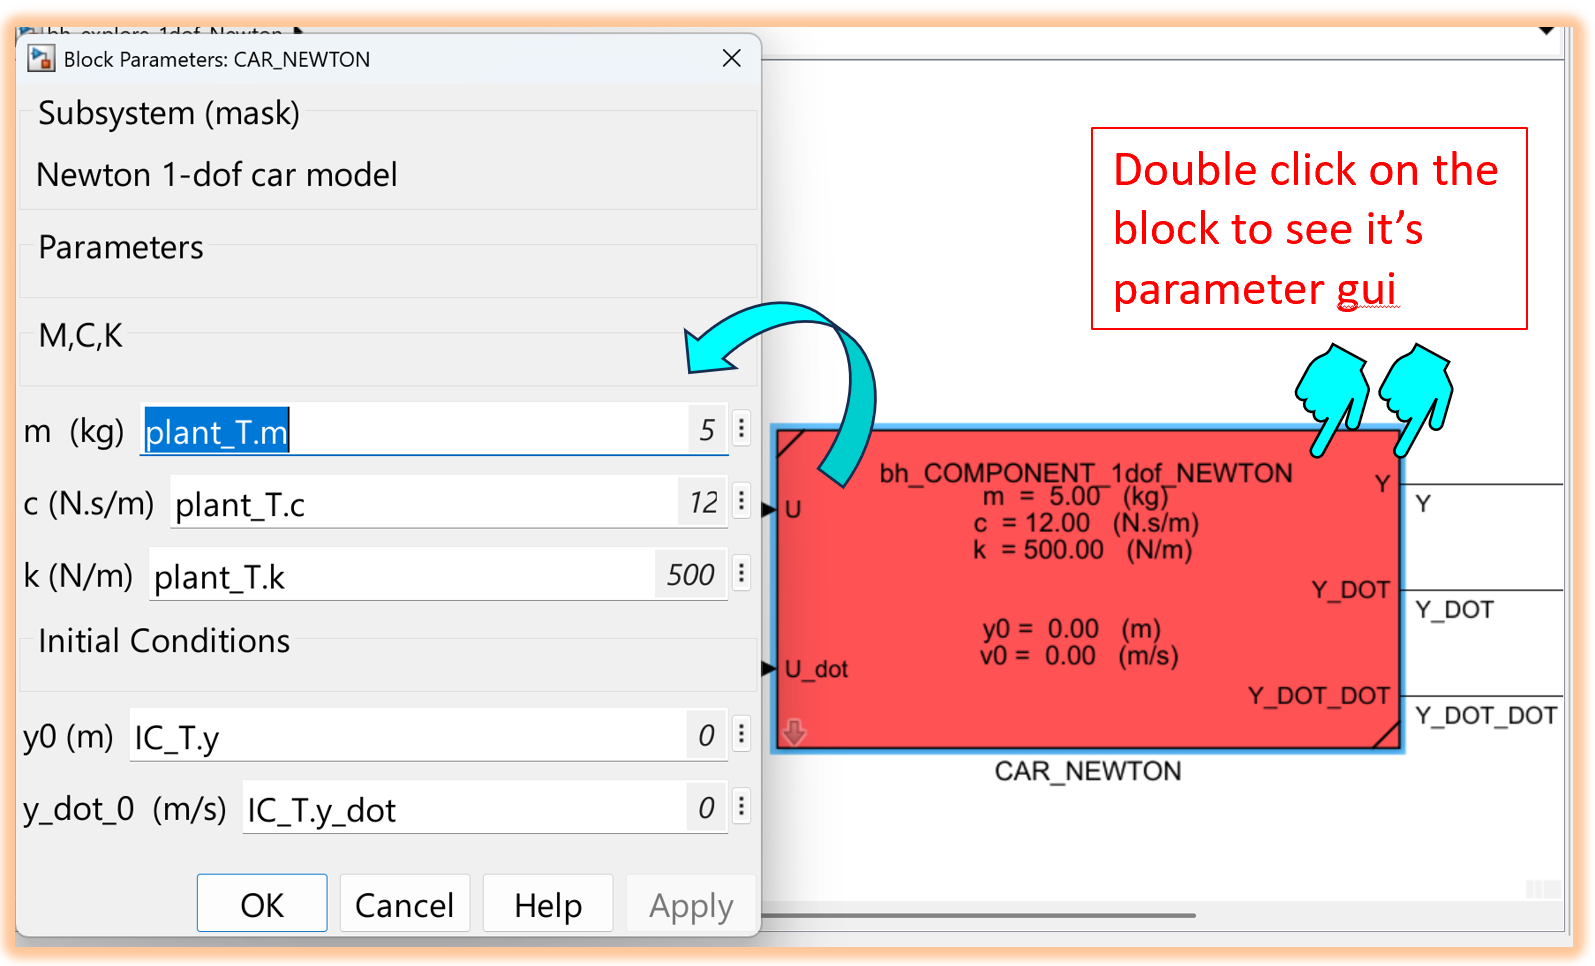

## STEP_01b:    Simscape model

Here's a snapshot of the Simulink model where we've used **Simscape Multibody** to represent the 1-dof car 

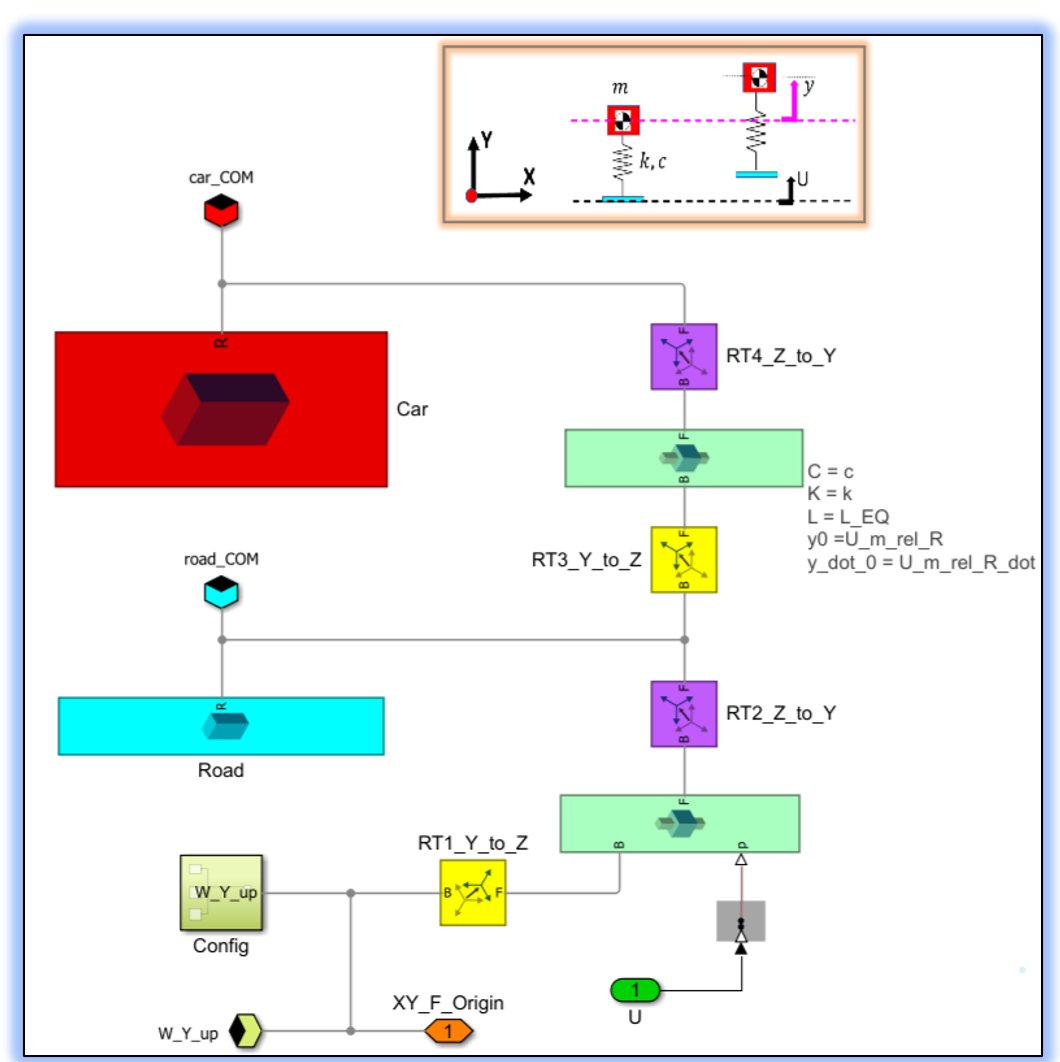

**Press** the button below to run this code section

Open the Simulink file:

open_system("bh_explore_1dof_Simscape.slx")

## STEP_01c:    Newton vs Simscape model

Here's a Simulink file where we **compare** the response of the Newton model against the Simscape Model 

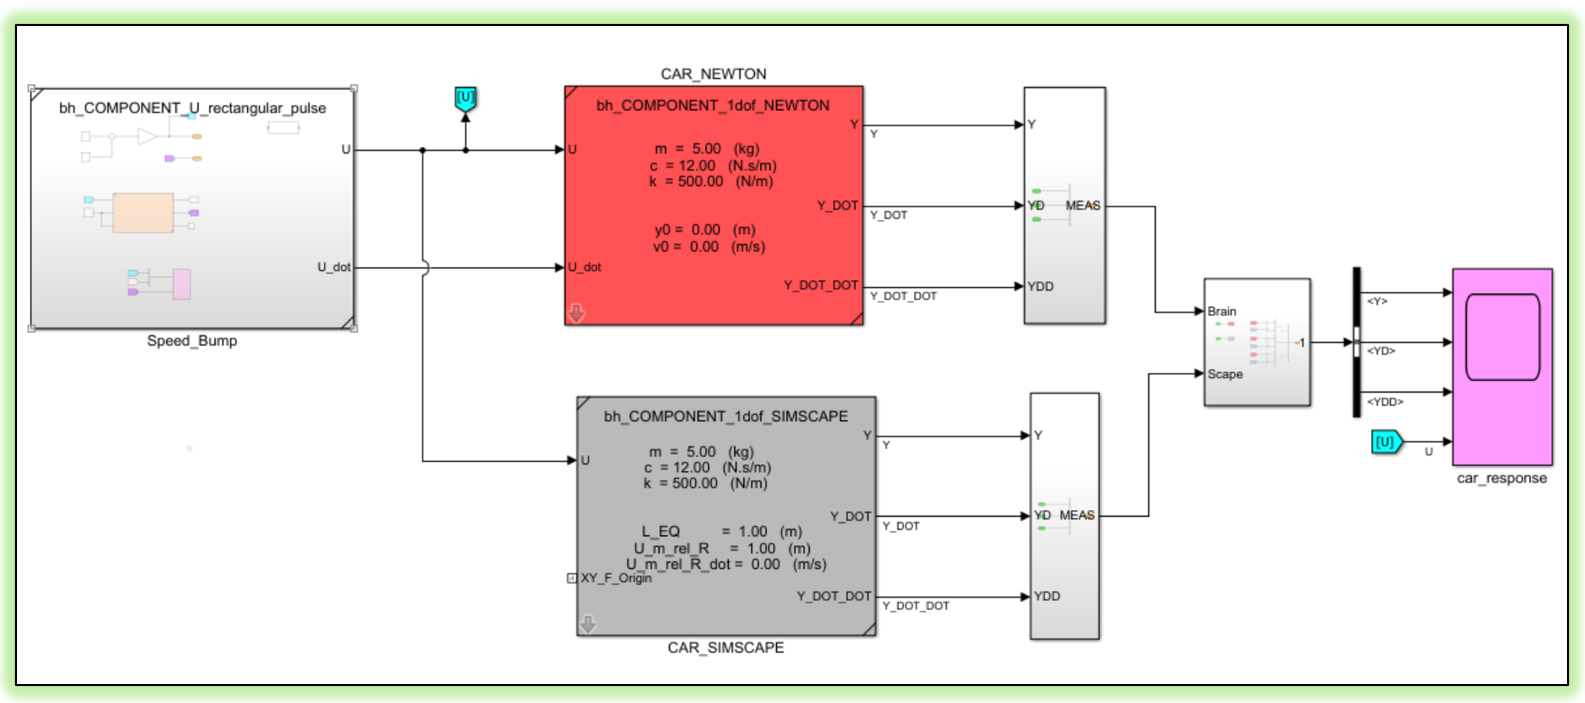

**Press** the button below to run this code section

Open the Simulink file:

open_system("bh_explore_1dof_Newton_vs_Simscape.slx")

## STEP_02:    Incorporate a ROAD profile model

Now let's simulate driving our 1-dof car over a road profile consisting of speed BUMPS.  Specifically our Road profile will look like this:

**Press** the button below to run this code section

Open the Simulink file:

open_system("bh_explore_1dof_on_the_ROAD.slx")